# zVA II - Compiling Extracted Vicon Data

Function 1:  [all_ank_trajs, all_knee_trajs, all_hip_trajs, avg_hip_ang_traj, avg_knee_a4ng_traj, avg_ank_ang_traj] = VAII_kinematics(vicon_file_data)

- Plots & outputs joint angle trajectories (deg) as % of gait cycle/stride

Function 2: [ankT_traj, kneeT_traj] = VAII_kinetics(vicon_file_data)

- Plots & outputs joint torques (N*m/Kg) over % of gait cycle/stride for ankle, knee and hip

Function 3: [step_len] = VAII_coordStrat(vicon_file_data)

- Computes average step length per subject across each trial

Several additional functions will need to be implemented to extract the biomechanical descriptors from the extracted data from the previous 3 functions.

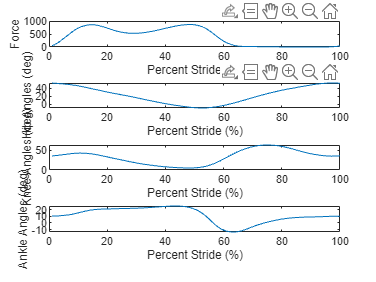

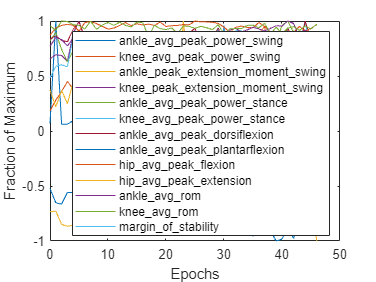

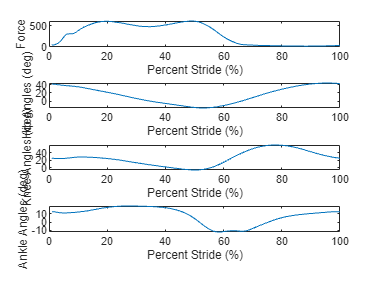

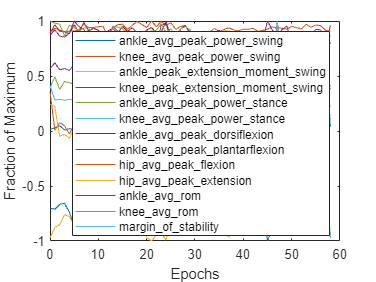

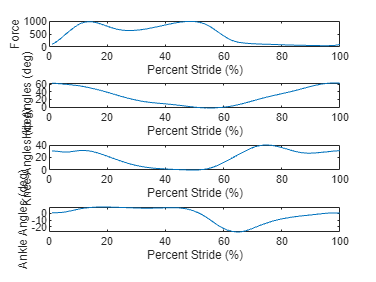

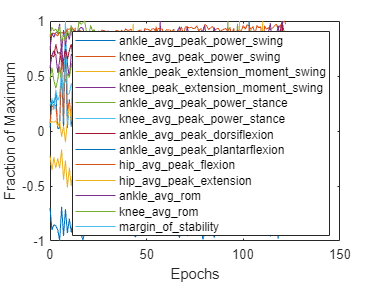

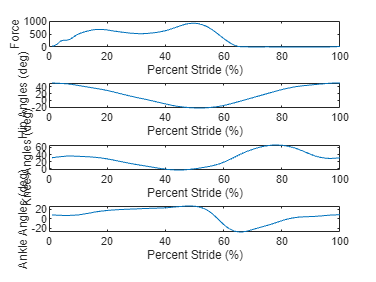

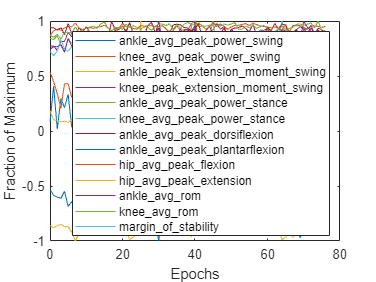

% clc; clear;

% navigate to proper Matlab path for VAII subject dictionary
%addpath('MATLAB')
addpath(genpath(pwd))

% loading in subject info from dictionary
[subject, all_subjects] = subject_dictionary;

% find which subjects don't have vicon files
no_vicon_dat_subjs = find(cellfun(@isempty,{subject.vicon}));

% compute # of subjects and which subjects have vicon files
tot_subjects = 1:length(all_subjects);
idxs = ismember(tot_subjects, no_vicon_dat_subjs);
subj_w_vicon_data = tot_subjects(~idxs);

packed_data = struct("dontuse", "dontuse");

% Looping thru each subject w/ vicon data 
for subj_num = subj_w_vicon_data(1):subj_w_vicon_data(end)

    % for each of the vicon filenames within 1 subject, 
    for data = 1:numel(subject(subj_num).vicon)

        % load the file
        vicon_fname = subject(subj_num).vicon(data);

        % Load Vicon data
        [vicon_file_data] = load(vicon_fname);
        extractName = all_subjects{subj_num};
        
        patCond = ("WNE"|"EPO");  % text searching pattern finds condition
        extractCond = extract(vicon_fname, patCond);

        % VAII_kinematics
        plot_strides = true;
        [name_cell_l, name_cell_r, strides_l, strides_r, swingstance_l, swingstance_r, stride_avg_l, stride_avg_r] = VAII_kinematics_full(vicon_file_data, subject, extractCond, extractName, plot_strides);
        
        % Biomechanical Descriptor Extract
        stepsize = 10;  % strides per group
        interval = 1;   % groups per epoch
        plot_desc = true;
        [descriptor_names_swing, descriptor_names_stance, descriptor_names_whole, descriptors_swing, descriptors_stance, descriptors_whole, func_names] = biomech_descriptor_extract(name_cell_l, name_cell_r, strides_l, strides_r, swingstance_l, swingstance_r, stepsize, interval, vicon_fname, plot_desc);
    
        % Save data to structs
        packed_data = packdata(vicon_fname, packed_data, name_cell_l, name_cell_r, strides_l, strides_r, swingstance_l, swingstance_r, stride_avg_l, stride_avg_r, func_names, descriptor_names_swing, descriptor_names_stance, descriptor_names_whole, descriptors_swing, descriptors_stance, descriptors_whole);
    end    
end


mvstruct = loadMV();

Functions

`packdata`

`    Save stride/descriptor data as structs to packed_data`

function packed_data = packdata(vicon_fname, packed_data, varargin)
    tempstruct = struct("dontuse", "dontuse");
    for i = 3:nargin
        tempstruct.(inputname(i)) = varargin(i-2);
    end
    tempstruct = rmfield(tempstruct, "dontuse");

    subject_name = split(vicon_fname, '_');

    packed_data.(subject_name{1}) = tempstruct;

    try
        packed_data = rmfield(packed_data, "dontuse");
    catch
        disp('')
    end
end